clear all

data=importdata("Triangle_Large_004_C1_vector_table_50grid_50window_gaussian.csv");

X=data.data(:,1);

Y=data.data(:,2);

dx=data.data(:,4);

dy=data.data(:,5);

Ori=data.data(:,6); %Orientation (in degrees angle)

En=data.data(:,8); %Energy 


theta1=reshape(Ori,241,142); %x=235, y=136 for 003, x=241, y=142 for 004,  x=248, y=146 for 006.
%for 45A45A90A we have: x=146, y=142 for 003. x=150, y=152 for 006. x=147, y=142 for 008.
%for 60A60A60A we have: x=141, y=132 for 005. x=135, y=117 for 006. x=142, y=126 for 015.
%for 120A30A30A we have: x=202, y=135 for 002. x=203, y=134 for 003. x=202,
%y=130 for 008.
theta1=transpose(theta1);

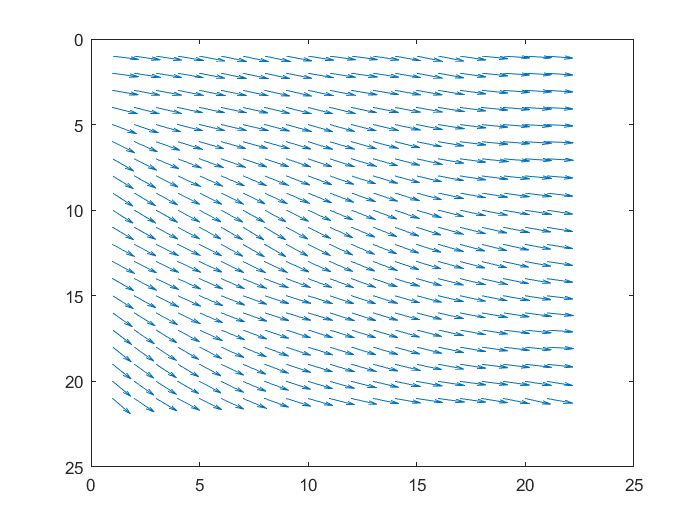

theta2=theta1(100:120,1:21)/180*pi;
%theta2=degree_state/180*pi;
%theta2=S;

%theta2=theta2(1:21,15:35);


theta2=rot90(theta2,3)+1*pi/2; %if i want it to go from the left hand side
%to the upper side of the matrix i choose 3 when i do rot90 and then i add
%pi/2 which means 90deg to the angle. If the arrows point the other way i
%subtract 90 degree. this way i can calculate alpha, although K1 and K3
%will be the same in all instances.

figure(1); quiver(cos(theta2),sin(theta2))
set (gca,'Ydir','reverse')


phi=transpose(theta2);
phi=reshape(phi,1,[]);
phi=transpose(phi);


H=size(theta2,1);
L=size(theta2,2);

E=zeros(H,L);

%load('Simulation_data.mat');
%SimData;


[M, M4, M9] = Matrixcalculation(H);


%K3 kan aldrig være mindre end K1, ellers skal jeg bare tage den absolutte
%værdi og dermed kender jeg kun forskellen mellem K3 og K1
cd('cube-main')
cd('path_to_cube')
obs=phi;
N=H*H;
model=struct('genu',@(obs) rand(1,3));
model.u2theta=@(u,obs) [-0.1*log(u(1))+1E-5, -10*log(u(2)), -10*log(u(3))]; %theta(1)=alpha and theta(2)=K1 and theta(3)=K3-K1
model.logl=@(phi,theta) logl(theta(1), theta(2), theta(3), obs, N, M, M4, M9);
model.labels={'alpha', 'K1', 'K3'};
results1=cube_main(obs,model);

After 500 processed samples: Zrat = 5.91e+07
After 1000 processed samples: Zrat = 3.93
After 1500 processed samples: Zrat = 0.209
After 2000 processed samples: Zrat = 0.0224
After 2500 processed samples: Zrat = 0.00215
Generated 2858 samples for Model 1.
CUBE is done.
Elapsed time is 181.819206 seconds.


function b1 = logl(alfa, K1, K3, obs, N, Matrix, M4, M9)

    Mat = Matrix + (K3/K1-1) * M9 + M4 * alfa; %her har vi divideret K1 på alle led
    
    M = chol(Mat, "lower");

    y = M' * obs;

    b1 = sum(log(diag(M))) - N * 0.5 * log(2 * pi / K1) - K1 / 2 * (y' * y);

end




% function [Matrix, M4, M9] = Matrixcalculation(H)
% Matrix1=-1*ones(H*H,H*H);
% Matrix2=3*ones(H*H,H*H);
% M2=zeros(H*H,H*H);
% M3=zeros(H*H,H*H);
% M6=zeros(H*H,H*H);
% M7=zeros(H*H,H*H);
% M8=zeros(H*H,H*H);
% for j=1:2
% k=1;
% if j>1
% M2=Matrix;
% end
%     if j==1  % code for odd
% for i=1:2
% if i>1
% M2=Matrix;
% end
% Matrix=diag(diag(Matrix1,k-H*(j-1)),k-H*(j-1))+1/2*diag(diag(Matrix2,H*(j-1)),H*(j-1));
% 
% M7=diag(diag(Matrix1,k-H*(j-1)),k-H*(j-1));
% 
% M8=diag(diag(Matrix1,-k-H*(j-1)),-k-H*(j-1));
% 
% Matrix=M2+Matrix;
% k=k-2;
% end
%     end
%     
% if j==2
% M2=Matrix;
% 
% Matrix=diag(diag(Matrix1,(1)-(H*(j-1)+1)),(1)-(H*(j-1)+1))+diag(diag(Matrix1,k+(H*(j-1)-1)),k+(H*(j-1)-1));
% Matrix=M2+Matrix;
% end
% 
% end
% 
% M4=zeros(H*H,H*H);
% for i=1:H
%     
%         M3((i-1)*H+1,(i-1)*H+1)=Matrix((i-1)*H+1,(i-1)*H+1)-3;%alfa
%         M6(i*H,i*H)=Matrix(i*H,i*H)-3;
%         
%         M4(i,i)=1;
%         
% end
% 
% Matrix=Matrix+M3+M6;
% 
% 
% for i=1+H:H*H-H
%     
%     Matrix(i,i)=Matrix(i,i)+3;
%     
% end
% 
% for i=2:H-1
% Matrix(i,i)=Matrix(i,i)+1;
% Matrix(H*(H-1)+i,H*(H-1)+i)=Matrix(H*(H-1)+i,H*(H-1)+i)+1;
% Matrix(H*(i-1)+1,H*(i-1)+1)=Matrix(H*(i-1)+1,H*(i-1)+1)-2;
% Matrix(H*i,H*i)=Matrix(H*i,H*i)-2;
% end
% 
% for i=1:H-1
%     Matrix(i*H+1,i*H)=0;
%     Matrix(i*H,i*H+1)=0;
%     M7(i*H+1,i*H)=0;
%     M8(i*H,i*H+1)=0;
% end
% Matrix=Matrix+M7+M8;
% M7=-1*M7;
% M8=-1*M8;
% M9=2*M7+2*M8;
% end






function [Matrix, M4, M9] = Matrixcalculation(H)
Matrix1=-1*ones(H*H,H*H);
Matrix2=3*ones(H*H,H*H);
M2=zeros(H*H,H*H);
M3=zeros(H*H,H*H);
M6=zeros(H*H,H*H);
M9=zeros(H*H,H*H);
for j=1:2
k=1;
if j>1
M2=Matrix;
end
    if j==1  % code for odd
for i=1:2
if i>1
M2=Matrix;
end
Matrix=diag(diag(Matrix1,k-H*(j-1)),k-H*(j-1))+1/2*diag(diag(Matrix2,H*(j-1)),H*(j-1));


Matrix=M2+Matrix;
k=k-2;
end
    end
    
if j==2
M2=Matrix;

Matrix=diag(diag(Matrix1,(1)-(H*(j-1)+1)),(1)-(H*(j-1)+1))+diag(diag(Matrix1,k+(H*(j-1)-1)),k+(H*(j-1)-1));
Matrix=M2+Matrix;
end

end

M4=zeros(H*H,H*H);
for i=1:H
    
        M3((i-1)*H+1,(i-1)*H+1)=Matrix((i-1)*H+1,(i-1)*H+1)-4;%alfa
        M6(i*H,i*H)=Matrix(i*H,i*H)-4;
        
        M4(i,i)=1;
        
end

Matrix=Matrix+M3+M6;


for i=1+H:H*H-H
    
    Matrix(i,i)=Matrix(i,i)+1;
    
end

for i=1:H-1
    Matrix(i*H+1,i*H)=0;
    Matrix(i*H,i*H+1)=0;
end

% Definer offset-naboer (venstre/højre i 2D gitter)
for i = 1:H*H
    if mod(i,H) ~= 0        % Ikke sidste i rækken
        M9(i,i+1) = - 1;
        M9(i+1,i) = - 1;
    end
end
for i = 1:H*H
    rowSum = sum(abs(M9(i,:)));
    M9(i,i) = rowSum*1;  % epsilon fx 1e-6
end
end





